# Práctica 6A. Métodos multipaso para EDOs

El objetivo de esta práctica es implementar y probar diferentes métodos multipaso para resolver la ecuación


$$\mathrm{(PVI)} \qquad \begin{cases}
\frac{d\mathbf{u}}{dt} (t) = \mathbf f (t, \mathbf u (t)) & t \in [t_0, T], \\
\mathbf u(t_0) = \mathbf u_0 
\end{cases}$$


## Método de Adams-Bashford de 4 pasos

Implementar una función que responda a la sintaxis

`[t, U] = AB4(f, inter, U0, N)`

que implemente el método de Adams-Bashford de 4 pasos


$$\mathbf U_{i+1} = \mathbf U_{i} + \frac h {24} \left(  55 \mathbf f_{i} - 59 \mathbf f_{i-1} + 37 \mathbf f_{i-2} - 9 \mathbf f_{i-3}    \right)$$


donde $\mathbf f_i = \mathbf f(t_i, \mathbf U_i)$, inicializado (es decir calculando $\mathbf U_1, \mathbf U_2, \mathbf U_3$) mediante el método RK4.

## Soluciones espurias y convergencia

Se considera el siguiente método:


$$\mathbf U_{i+1} = \mathbf U_{i-3} + \frac {4h} 3 \left(  2\mathbf f_{i} - \mathbf f_{i-1} + 2 \mathbf f_{i-2}    \right)$$


donde $\mathbf f_i = \mathbf f(t_i, \mathbf U_i)$. La raíces de su polinomio asociado $\rho(z) = z^4-1$ se encuentran todas en la circunferencia unidad. El método es 0-estable. Estos métodos, aunque convergentes, pueden generar soluciones espurias. 

a) Implementar en el apéndice A2 una función que responda a la sintaxis

`[t, U] = MilneExp4(f,inter,U0,N)`

que implemente este método, inicializado (es decir calculando $\mathbf U_1, \mathbf U_2, \mathbf U_3$) mediante el método RK4.

b) Comprobar que para el péndulo


$$\begin{cases}
\ddot \theta + \dot \theta + 9.8 \sin(\theta)=1 & t \in [0,10]\\
\theta(0) = 0.1 \\
\dot \theta(0) = 0
\end{cases}$$


aparecen soluciones extrañas. Representar $(t,\theta(t))$ y el diagrama de fases $(\theta(t), \dot \theta(t))$ en los siguientes casos

- N = 100.

- N = 1000. Comparar con las obtenidas por el método de Adams-Bashforth de orden 4 evaluado en 100 puntos.

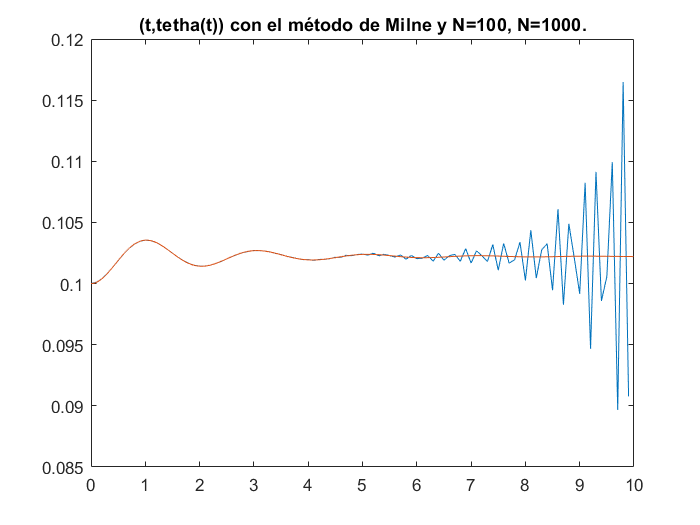

clear all
clc
clf
f = @(t,U) ([0,1;0,-1]*U + [0;1 - 9.8 * sin(U(1))]);
U0 = [0.1;0];
inter = [0,10];

%Gráfica (t,tetha(t)) con el método de Milne y N=100, N=1000.
N=100;
[t, U] = MilneExp4(f,inter,U0,N);
plot(t,U(1,:))
hold on
N=1000;
[t, U] = MilneExp4(f,inter,U0,N);
plot(t,U(1,:))
title('(t,tetha(t)) con el método de Milne y N=100, N=1000.')
hold off

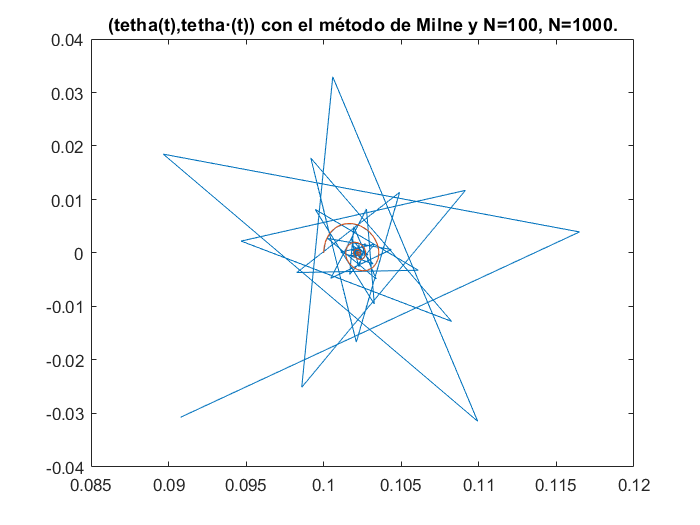


%Gráfica (tetha(t),tetha'(t)) con el método de Milne y N=100, N=1000.
N=100;
[t, U] = MilneExp4(f,inter,U0,N);
plot(U(1,:),U(2,:))
hold on
N=1000;
[t, U] = MilneExp4(f,inter,U0,N);
plot(U(1,:),U(2,:))
title('(tetha(t),tetha·(t)) con el método de Milne y N=100, N=1000.')
hold off

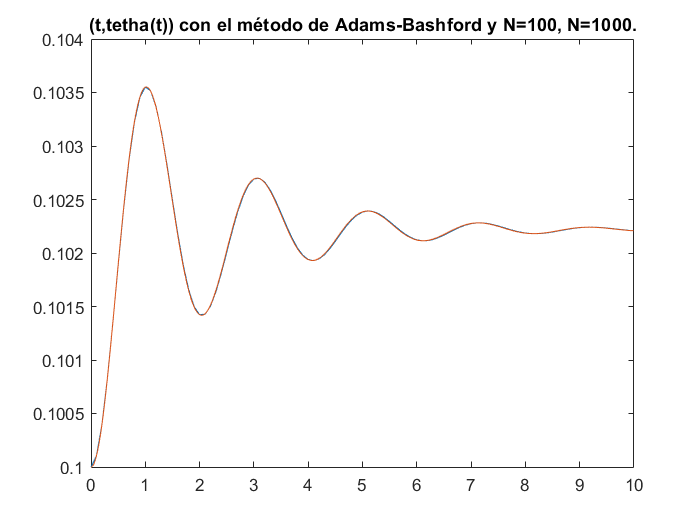


%Gráfica (t,tetha(t)) con el método de Adams-Bashford y N=100, N=1000.
N=100;
[t,U] = AB4(f, inter, U0, N);
plot(t,U(1,:))
hold on
N=1000;
[t,U] = AB4(f, inter, U0, N);
plot(t,U(1,:))
title('(t,tetha(t)) con el método de Adams-Bashford y N=100, N=1000.')
hold off

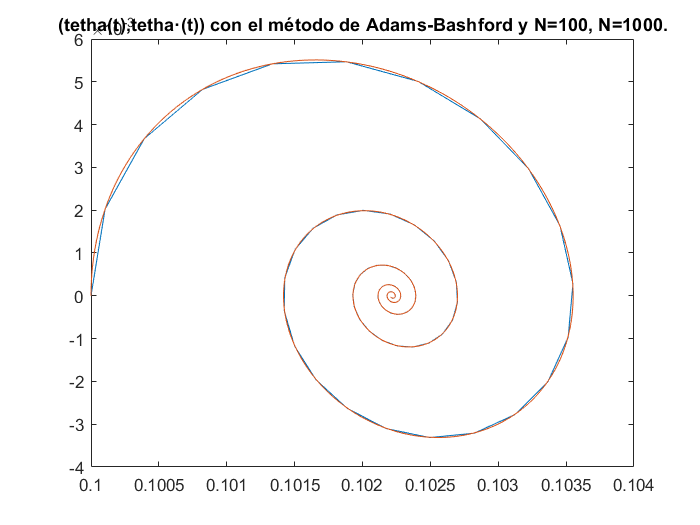


%Gráfica (tetha(t),tetha'(t)) con el método de Adams-Bashford y N=100, N=1000.
N=100;
[t,U] = AB4(f, inter, U0, N);
plot(U(1,:),U(2,:))
hold on
N=1000;
[t,U] = AB4(f, inter, U0, N);
plot(U(1,:),U(2,:))
title('(tetha(t),tetha·(t)) con el método de Adams-Bashford y N=100, N=1000.')
hold off

## Apéndice

### Método de Adams-Bashforth de 2 pasos

function [t,U] = AB4(f, inter, U0, N)
[t,U]=RK4(f,inter,U0,N);
t_0 = inter(1);
T = inter(2);
h = (T-t_0)/N;
for i=1:N-4
    t(i+4)=t(i+3)+h;
    U(:,i+4) = U(:,i+3)+h/24*(55*f(t(i+3),U(:,i+3))-59*f(t(i+2),U(:,i+2))+37*f(t(i+1),U(:,i+1))-9*f(t(i),U(:,i)));
end
end
%Usamos el método de RungeKuta para inicializar.
function [t,U]=RK4(f,t_interv,u_0,N)
t_0 = t_interv(1);
T = t_interv(2);
h = (T-t_0)/N;
t(1) = t_0;
U(:, 1) = u_0;
for i=1:3   %Solo queremos los cuatro primeros Ui.
    t(i+1)=t(i) +h;
    F1 = f(t(i),U(:,i));
    F2 = f(t(i)+h/2,U(:,i)+h*F1/2);
    F3 = f(t(i)+h/2,U(:,i)+h*F2/2);
    F4 = f(t(i)+h,U(:,i)+h*F3);
    U(:,i+1) = U(:,i) +h/6*(F1+2*F2+2*F3+F4);
end
end

### Método de Milne explícito de 4 pasos

function [t, U] = MilneExp4(f,inter,U0,N)
[t,U]=RK4(f,inter,U0,N);
t_0 = inter(1);
T = inter(2);
h = (T-t_0)/N;
for i=4:N-1
    t(i+1)=t(i)+h;
    U(:,i+1)=U(:,i-3)+(4*h/3)*(2*f(t(i),U(:,i))- f(t(i-1),U(:,i-1))+2*f(t(i-2),U(:,i-2)));
end
end